clear all;
load fisheriris.mat


meas

meas =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


species

species = 150×1 cell array
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    

sepal = meas(: , 1) ./ meas(: , 2)

sepal =     1.4571
    1.6333
    1.4688
    1.4839
    1.3889
    1.3846
    1.3529
    1.4706
    1.5172
    1.5806


petal = meas(: , 3) ./ meas(: , 4)

petal =     7.0000
    7.0000
    6.5000
    7.5000
    7.0000
    4.2500
    4.6667
    7.5000
    7.0000
   15.0000


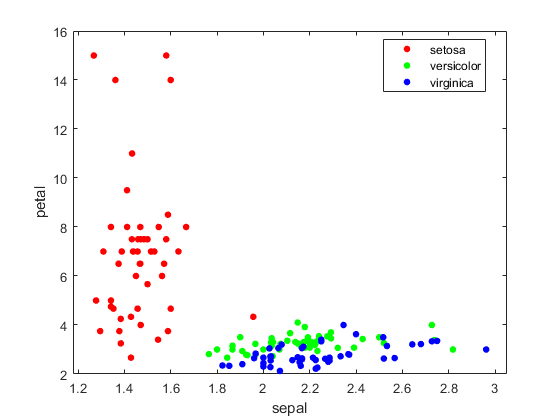

gscatter(sepal, petal, species)

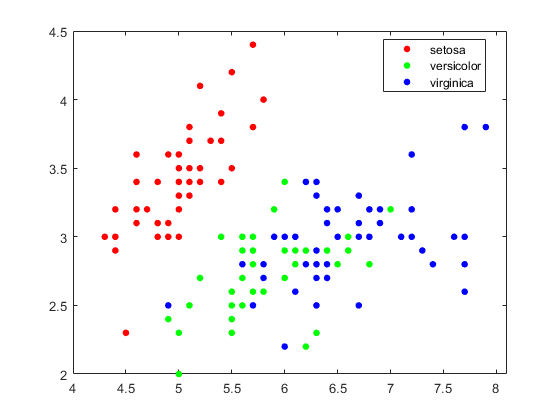

gscatter(meas(:, 1), meas(: , 2) , species)

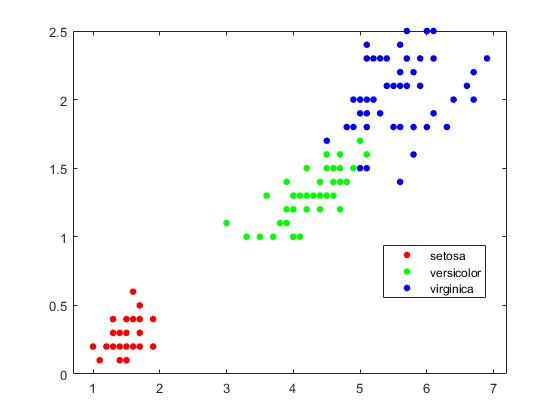

gscatter(meas(:, 3), meas(: , 4) , species)

cv = cvpartition(species, "HoldOut", 0.2)

cv = Hold-out cross validation partition
   NumObservations: 150
       NumTestSets: 1
         TrainSize: 120
          TestSize: 30

trainMeasure = meas(cv.training, :);
trainSpecies = species(cv.training, :);
testMeasure = meas(cv.test, :);
testSpecies = species(cv.test, :);


Model = fitcknn(trainMeasure, trainSpecies, "NumNeighbors", 5, "Standardize", 1)

Model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 120
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


pred = predict(Model, testMeasure)

pred = 30×1 cell array
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }


predString = string(pred);
correct = predString == testSpecies;
accuracy = sum(correct)/numel(pred);

wrong = predString ~= testSpecies;
misclassrate = sum(wrong)/numel(pred)

misclassrate = 0.0333

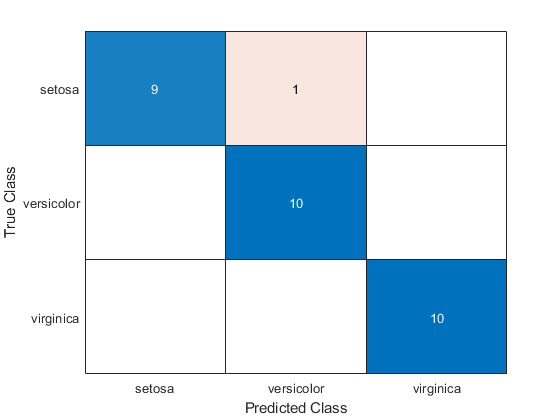

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: {3×1 cell}

  Show all properties



confusionchart(testSpecies, pred)